clear; close all; clc; % initializes environment

# 分散共分散行列の逆行列と幾何学的解釈

## 本章の目的

前章では，$\mathrm{PCA}$の幾何学的解釈として，楕円を用いた解説を行いました．そこでは，正射影ベクトルの長さの分散$S=\left(u,\mathit{Vu}\right)$や$S=\left(u\prime ,\mathit{Du}\prime \right)$を三次元空間上のグラフととらえたうえで，高さが$1$の平面でグラフを切断した面として楕円をとらえました．それによって，楕円の短軸および長軸が座標軸にと重なり，それぞれの切片が分散共分散行列$V$の固有値$\lambda_1$および$\lambda_2$を用いて，$\pm 1/\sqrt{\lambda_1 }$および$\pm 1/\sqrt{\lambda_2 }$となることを解説しました．また，データの分布との比較によって，楕円の短軸方向はデータがもっとも広がっている方向と一致することを紹介しました．

本章では，分散共分散行列$V$の逆行列$V^{-1}$を用いた二次形式$\left(u,V^{-1} u\right)$について幾何学的に解説していきます．

## データの準備

### データの読み込み

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

### データ行列の作成

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

### 分散共分散行列$V$の固有ベクトルおよび固有値

eig()関数を用いて以下のように求めることができました．

[Q,D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここで，行列$Q$の各列が分散共分散行列$V$の固有ベクトルです．また，行列$D$は対角成分が固有値となる対角行列です．対角成分が左上から降順に並ぶように並び替えます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


### pca()関数を用いた主成分分析

pca()関数を用いてデータ行列の主成分係数と主成分スコアを求めます．

[coefs,scores] = pca(X','Algorithm','eig')

coefs =     0.7071   -0.7071
    0.7071    0.7071


scores =    -0.9971    0.3406
    0.6991    0.0360
   -0.8441   -0.0436
    0.4020    0.0562
    0.6753   -0.2655
   -0.8138   -0.0443
   -0.5227    0.2736
   -0.4091   -0.0978
   -0.9723    0.0904
   -0.6561    0.0725


## $\mathrm{S}=\left(u,\mathit{Vu}\right)$の視覚的イメージ（復習）

これまで，正射影ベクトルの長さの分散$\mathrm{S}=\left(u,\mathit{Vu}\right)$の幾何学的イメージとして，


$$\begin{array}{l}
{\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
{{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1
\end{array}$$


で表される曲線や，


$$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)=1$$


で表される楕円を紹介してきました．以下に，実際のデータの分布とともに再掲します．

figure('Name','Fig.10-1: S=(u,Vu)');
subplot(1,3,1); 
xt = @(t) cos(t);
yt = @(t) sin(t);
zt = @(t) V(1,1)*cos(t)^2 + 2*V(1,2)*cos(t)*sin(t) + V(2,2)*sin(t)^2;
fplot3(xt,yt,zt,'r-'); 

axis([-1.5 1.5 -1.5 1.5 0 3]); axis square; 
title('x_3 = f(x_1,x_2) where x1^2+x2^2=1');
zlabel('x_3'); ylabel('x_2'); xlabel('x_1'); hold on;
fplot3(xt,yt,@(t)0,'b:');

scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');

subplot(1,3,2); title('f(x_1,x_2) = 1'); hold on; grid on;
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
plot(t, y1, 'r-'); plot(t, y2, 'r-');

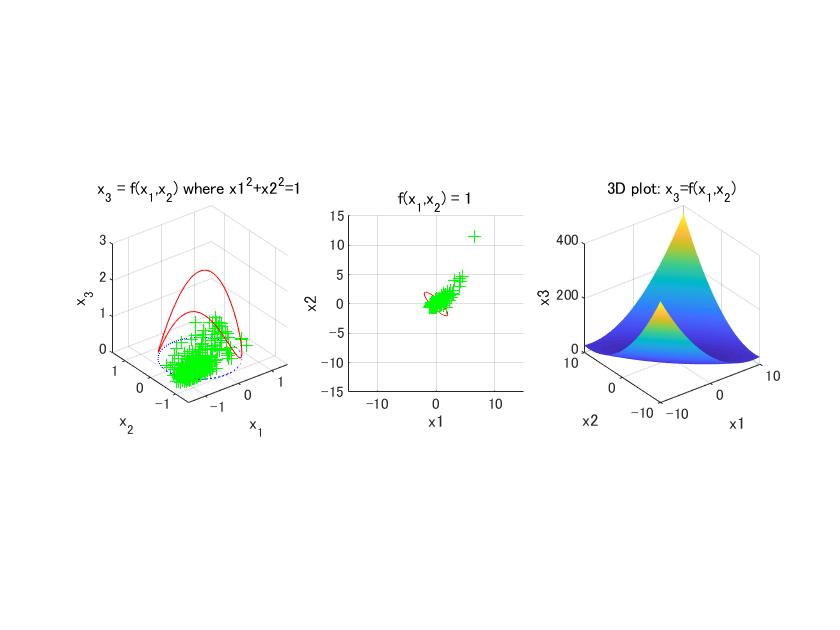

scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
xlabel('x1'); ylabel('x2');
axis([-15 15 -15 15]); axis square;

subplot(1,3,3);
[x1grid,x2grid] = meshgrid(-10:0.01:10, -10:0.01:10);
x3 = V(1,1)*x1grid.^2 + 2*V(1,2)*x1grid.*x2grid + V(2,2)*x2grid.^2;
s = surf(x1grid,x2grid,x3); title('3D plot: x_3=f(x_1,x_2)');
xlabel('x1'); ylabel('x2'); zlabel('x3');
s.EdgeColor = 'none'; axis square;

左図の赤い実線が${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の曲線（ただし${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$）で，真ん中の図の赤い実線が$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$の楕円です．緑色の十字で中心化されたデータの分布を表しています．左図の曲線は，右図の曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$において，定義域を${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$とした場合，つまり曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$と単位円柱${{\mathrm{x}}_1 }^2 +{{\mathrm{x}}_2 }^2 =1$の交点として表されます．また，真ん中の図の楕円は，曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の，${\mathrm{x}}_3 =1$における断面を表します．いずれの場合も，曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配がグラフ（右図）の形を決めます．曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配は，データの広がりが大きいほどきつくなります．つまり，データの広がりが大きいほど，曲面の勾配は大きくなり，関数$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の値はいち早く大きくなります．その結果，左図の曲線では，データの広がりが最も大きい方向で最大値をむかえます．また，真ん中の楕円では，データの広がりが最も大きい方向と楕円の短軸方向が一致します．

## データの分布を最もよく表すのは$\left(x,V^{-1} x\right)=1$

さて，ここで楕円$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$とデータの分布の関係に着目してみましょう．先程も触れたように，データがもっとも広がっている方向と楕円の短軸方向が一致します．また，データの広がりがもっとも小さい方向と楕円の長軸方向が一致します．これは，曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の勾配が大きいほど，より早く$f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$に達するためです．曲面${\mathrm{x}}_3 =f\left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$のイメージを意識しないと楕円とデータの分布の関係を直感的に理解することは難しいため，本稿では楕円の解説は先送りして，主に曲面のイメージを使って解説してきました．ここでは，データの分布をより直感的に表すことが出来る楕円を紹介します．


$$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$$


という関数について，$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$で表される曲線を考えます．ここで，$V^{-1}$は分散共分散行列$V$の逆行列です．


$$V=\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack$$


のとき，その逆行列$V^{-1}$は

Vinv = inv(V)

Vinv =     4.0058   -3.4682
   -3.4682    4.0058


となります．このとき，関数$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$は


$$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=4\ldotp 0058{{\mathrm{x}}_1 }^2 +2\times \left(-3\ldotp 4682\right){\mathrm{x}}_1 {\mathrm{x}}_2 +4\ldotp 0058{{\mathrm{x}}_2 }^2 =1$$


となります．このグラフを以下に示します．

figure(); title('\phi(x_1,x_2) = 1'); hold on; grid on;
scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
% 4.0058x^2 - 2*3.4682xy + 4.0058y^2 = 1 % cf) WolframAlpha
t = linspace(-0.998478, 0.998478, 1000);
y1 = (2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
y2 = (-2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
plot(t, y1, 'b-'); plot(t, y2, 'b-');

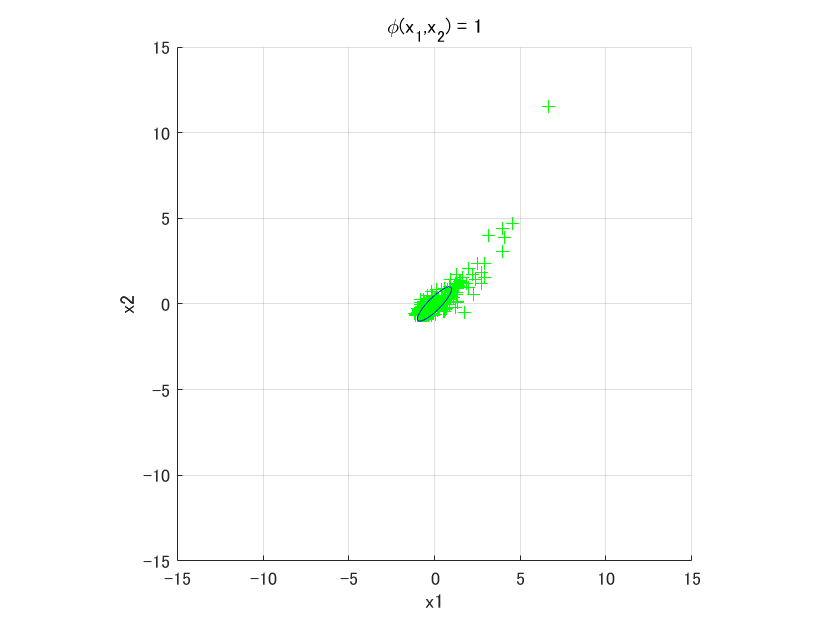

xlabel('x1'); ylabel('x2');
axis([-15 15 -15 15]); axis square;

青い実線が$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=1$です．データの分布と楕円の形がよく似ているのがわかります．じつは，データの分布をもっともよく表すのは，$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(x,V^{-1} x\right)=1$という関数です．

## $\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(x,V^{-1} x\right)$の標準化

関数$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$は二次形式です．これを標準形に変換してみます．分散共分散行列$V$の固有値分解を


$$V=\mathit{QD}Q^T$$


とします．ただし，$D$は分散共分散行列$V$の固有値を降順に対角成分に並べた対角行列です．また，$Q$は分散共分散行列$V$の固有ベクトルを列成分とする行列です．このとき，行列$V$の逆行列は


$$\begin{array}{l}
V^{-1} ={\left(\mathit{QD}Q^T \right)}^{-1} \\
\;\;\;\;\;\;\;\;={\left(Q^T \right)}^{-1} D^{-1} Q^{-1} \\
\;\;\;\;\;\;\;\;=QD^{-1} Q^T 
\end{array}$$


となります．なお，上記の式変形において，行列$Q$が直交行列（$Q^T =Q^{-1}$）であることを利用しました．これを


$$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$$


に代入します．


$$\begin{array}{l}
\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,QD^{-1} Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,D^{-1} Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack ,D^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack \right)
\end{array}$$


となります．ただし，$\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$としました．この変換は二次形式$f\left(x_1 ,x_2 \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$の標準化の際のものと同じものです．ここで，$D=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack$（ただし，$\lambda_1 >\lambda_2$）とすると，


$$D^{-1} =\left\lbrack \begin{array}{cc}
\frac{1}{\lambda_1 } & 0\\
0 & \frac{1}{\lambda_2 }
\end{array}\right\rbrack$$


となります．これを$\phi \left({\mathrm{x}}_1 ,{\mathrm{x}}_2 \right)$の標準形に代入すると，


$$\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\frac{{x_1 \prime }^2 }{\lambda_1 }+\frac{{x_2 \prime }^2 }{\lambda_2 }=\frac{{x_1 \prime }^2 }{{\left(\sqrt{\lambda_1 }\right)}^2 }+\frac{{x_2 \prime }^2 }{{\left(\sqrt{\lambda_2 }\right)}^2 }$$


となります．$\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$とすると，これも楕円の方程式になることがわかります．

## $\left(x,\textrm{Vx}\right)$と$\left(x,V^{-1} x\right)$の関係

まず，関数$f\left(x,\mathit{Vx}\right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$と関数$\phi \left(x,V^{-1} x\right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,V^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack \right)$として，


$$\begin{array}{l}
f\left(x,\textrm{Vx}\right)=1\\
\phi \left(x,V^{-1} x\right)=1
\end{array}$$


で表されるグラフを比較してみます．

figure();
subplot(1,2,1); title('f(x_1,x_2) = 1'); hold on; grid on;
scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
plot(t, y1, 'r-'); plot(t, y2, 'r-');

xlabel('x1'); ylabel('x2');
axis([-15 15 -15 15]); axis square;

subplot(1,2,2); title('\phi(x_1,x_2) = 1'); hold on; grid on;
scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
% 4.0058x^2 - 2*3.4682xy + 4.0058y^2 = 1 % cf) WolframAlpha
t = linspace(-0.998478, 0.998478, 1000);
y1 = (2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
y2 = (-2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
plot(t, y1, 'b-'); plot(t, y2, 'b-');

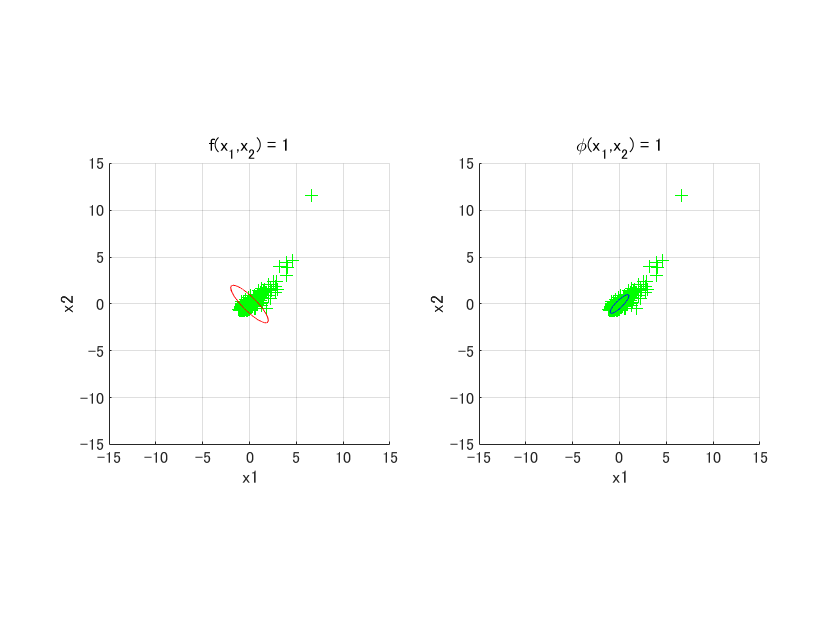


xlabel('x1'); ylabel('x2');
axis([-15 15 -15 15]); axis square;

左図の赤い実線が$f\left(x,\textrm{Vx}\right)=1$で表される楕円で，右側の青い実線が$\phi \left(x,V^{-1} x\right)=1$で表される楕円です．緑色の十字は中心化されたデータの分布です．先程のセクションで指摘したように，$\phi \left(x,V^{-1} x\right)=1$で表される楕円の方が実際のデータの分布をよく表しているようにみえます．

### 標準形の比較

次に，両者の標準形を見比べてみます．それぞれの標準形は


$$\begin{array}{l}
g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack ,D\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack \right)=\lambda_1 {{\mathrm{x}}_1 }^2 +\lambda_2 {{\mathrm{x}}_2 }^2 \\
\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack ,D^{-1} \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack \right)=\frac{1}{\lambda_1 }{{\mathrm{x}}_1 }^2 +\frac{1}{\lambda_2 }{{\mathrm{x}}_2 }^2 
\end{array}$$


となります．ただし，$\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \prime \\
{\mathrm{x}}_2 \prime 
\end{array}\right\rbrack =Q^T \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack$です．楕円の方程式の形で表すと以下のようになります．


$$\begin{array}{l}
g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\frac{{x_1 \prime }^2 }{{\left(1/\sqrt{\lambda_1 }\right)}^2 }+\frac{{x_2 \prime }^2 }{{\left(1/\sqrt{\lambda_2 }\right)}^2 }=1\\
\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=\frac{{x_1 \prime }^2 }{{\left(\sqrt{\lambda_1 }\right)}^2 }+\frac{{x_2 \prime }^2 }{{\left(\sqrt{\lambda_2 }\right)}^2 }=1
\end{array}$$


両者を見比べると，各軸の切片の値が違うのがわかります．$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$において，${\mathrm{x}}_1 \prime$軸（${\mathrm{x}}_2 \prime =0$）の切片は${\mathrm{x}}_1 \prime =\pm 1/\sqrt{\lambda_1 }$です．また，${\mathrm{x}}_2 \prime$軸（${\mathrm{x}}_1 \prime =0$）の切片は${\mathrm{x}}_2 \prime =\pm 1/\sqrt{\lambda_2 }$です．一方，$\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$では，${\mathrm{x}}_1 \prime$軸（${\mathrm{x}}_2 \prime =0$）の切片は${\mathrm{x}}_1 \prime =\pm \sqrt{\lambda_1 }$，${\mathrm{x}}_2 \prime$軸（${\mathrm{x}}_1 \prime =0$）の切片は${\mathrm{x}}_2 \prime =\pm \sqrt{\lambda_2 }$となります．グラフにして見比べてみましょう．

figure();
subplot(1,2,1); title('g(x_1'',x_2'')=1'); hold on; grid on;
% plot rotated data
Xrot = Q'*X; scatter3(Xrot(1,:),Xrot(2,:),zeros(size(X(1,:))),'c+');
% indicate intercepts
plot([-1/sqrt(D(1,1)) 1/sqrt(D(1,1))],zeros(1,2),'s','MarkerFaceColor','k');
text(-1/sqrt(D(1,1)),0,'[-1/\lambda_1^{1/2}, 0]^{T}','HorizontalAlignment','right','VerticalAlignment','bottom');
text(1/sqrt(D(1,1)),0,'[1/\lambda_1^{1/2}, 0]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');
plot(zeros(1,2),[-1/sqrt(D(2,2)) 1/sqrt(D(2,2))],'d','MarkerFaceColor','k');
text(0,1/sqrt(D(2,2)),'[0, 1/\lambda_2^{1/2}]^{T}','HorizontalAlignment','left','VerticalAlignment','bottom');
text(0,-1/sqrt(D(2,2)),'[0, -1/\lambda_2^{1/2}]^{T}','HorizontalAlignment','left','VerticalAlignment','top');
% 1.8601x^2 + 0.1338y^2 = 1 % cf) WolframAlpha
t = linspace(-1/sqrt(D(1,1)), 1/sqrt(D(1,1)), 1000);
y1 = (sqrt(10000-18601*t.^2)) / sqrt(1338);
y2 = -(sqrt(10000-18601*t.^2)) / sqrt(1338);
plot(t, y1, 'r-'); hold on; plot(t, y2, 'r-');
xlabel('x1'''); ylabel('x2'''); 
axis([-5 5 -5 5]); axis square;

subplot(1,2,2); title('\phi(x_1'',x_2'')=1'); hold on; grid on;
% plot rotated data
Xrot = Q'*X; scatter3(Xrot(1,:),Xrot(2,:),zeros(size(X(1,:))),'c+');
% indicate intercepts
plot([-sqrt(D(1,1)) sqrt(D(1,1))],zeros(1,2),'s','MarkerFaceColor','k');
text(-sqrt(D(1,1)),0,'[-\lambda_1^{1/2}, 0]^{T}','HorizontalAlignment','right','VerticalAlignment','middle');
text(sqrt(D(1,1)),0,'[\lambda_1^{1/2}, 0]^{T}','HorizontalAlignment','left','VerticalAlignment','middle');
plot(zeros(1,2),[-sqrt(D(2,2)) sqrt(D(2,2))],'d','MarkerFaceColor','k');
text(0,sqrt(D(2,2)),'[0, \lambda_2^{1/2}]^{T}','HorizontalAlignment','center','VerticalAlignment','bottom');
text(0,-sqrt(D(2,2)),'[0, -\lambda_2^{1/2}]^{T}','HorizontalAlignment','center','VerticalAlignment','top');
% (1/1.8601)x^2 + (1/0.1338)y^2 = 1 % cf) WolframAlpha
t = linspace(-sqrt(D(1,1)), sqrt(D(1,1)), 1000);
y1 = (1/50)*sqrt(669/37202)*sqrt(18601-10000*t.^2);
y2 = -(1/50)*sqrt(669/37202)*sqrt(18601-10000*t.^2);
plot(t, y1, 'b-'); hold on; plot(t, y2, 'b-');

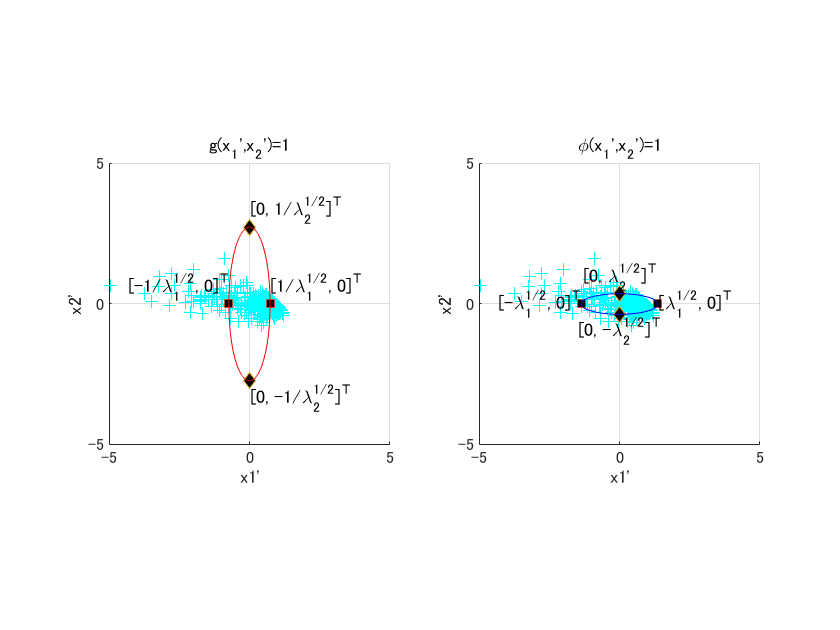

xlabel('x1'''); ylabel('x2'''); 
axis([-5 5 -5 5]); axis square;

左図の赤い実線が$g\left(x\prime ,\textrm{Dx}\prime \right)=1$で表される楕円で，右側の青い実線が$\varphi \left(x\prime ,D^{-1} x\prime \right)=1$で表される楕円です．水色の十字は中心化されたデータを$x\prime =Q^T x$によって回転させた分布です．標準化後も，$\varphi \left(x,V^{-1} x\right)=1$で表される楕円の方がデータの分布をよく表しているようにみえます．それぞれの切片を見てみると，$g\left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$において，${\mathrm{x}}_1 \prime$軸（${\mathrm{x}}_2 \prime =0$）の切片は${\mathrm{x}}_1 \prime =\pm 1/\sqrt{\lambda_1 }$です．また，${\mathrm{x}}_2 \prime$軸（${\mathrm{x}}_1 \prime =0$）の切片は${\mathrm{x}}_2 \prime =\pm 1/\sqrt{\lambda_2 }$です（四角）．一方，$\varphi \left({\mathrm{x}}_1 \prime ,{\mathrm{x}}_2 \prime \right)=1$において，${\mathrm{x}}_1 \prime$軸（${\mathrm{x}}_2 \prime =0$）の切片は${\mathrm{x}}_1 \prime =\pm \sqrt{\lambda_1 }$，${\mathrm{x}}_2 \prime$軸（${\mathrm{x}}_1 \prime =0$）の切片は${\mathrm{x}}_2 \prime =\pm \sqrt{\lambda_2 }$となります（菱形）．

## $V$と$V^{-1}$の固有ベクトル

最後に，分散共分散行列$V$とその逆行列$V^{-1}$の固有ベクトルを比べてみましょう．

まず，固有値分解を見比べると，


$$\begin{array}{l}
V=\mathit{QD}Q^T \\
V^{-1} =QD^{-1} Q^T 
\end{array}$$


となります．ここで，$D$は分散共分散行列$V$の固有値を対角成分に降順に並べた対角行列です．また，$Q$は分散共分散行列$V$の固有ベクトルを列成分とする行列です．いま，分散共分散行列$V$の固有値を$\lambda_1 ,\lambda_2$（$\lambda_1 >\lambda_2$），それぞれの固有値に対応する固有ベクトルを$q^{\left(1\right)} ,q^{\left(2\right)}$とすると，行列$D$および$Q$は


$$\begin{array}{l}
D=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack \\
Q=\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack 
\end{array}$$


と表すことが出来ます．これらの表記を用いて，分散共分散行列$V$とその逆行列$V^{-1}$の固有値分解を表すと以下のようになります．


$$\begin{array}{l}
V=\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack }^T =\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{q^{\left(1\right)} }^T \\
{q^{\left(2\right)} }^T 
\end{array}\right\rbrack \\
V^{-1} =\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\frac{1}{\lambda_1 } & 0\\
0 & \frac{1}{\lambda_2 }
\end{array}\right\rbrack {\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack }^T =\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
\frac{1}{\lambda_1 } & 0\\
0 & \frac{1}{\lambda_2 }
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{q^{\left(1\right)} }^T \\
{q^{\left(2\right)} }^T 
\end{array}\right\rbrack 
\end{array}$$


両者を見比べると，違いは対角行列$D$および$D^{-1}$のみで，固有ベクトルを並べた行列$Q$は共通です．また，対角行列も対角成分がそれぞれ逆数になっているだけで，固有ベクトルとの対応関係は変わりません．つまり，分散共分散行列$V$の固有値を$\lambda_1 ,\lambda_2$（$\lambda_1 >\lambda_2 >0$），それぞれの固有値に対応する固有ベクトルを$q^{\left(1\right)} ,q^{\left(2\right)}$としたとき，$V^{-1}$の固有値は$1/\lambda_1 ,1/\lambda_2$（$1/\lambda_2 >1/\lambda_1 >0$）となり，それぞれの固有値に対応する固有ベクトルは$q^{\left(1\right)} ,q^{\left(2\right)}$となります．言い換えると，分散共分散行列$V$の最大固有値$\lambda_1$の逆数が$V^{-1}$の最小固有値$1/\lambda_1$となり，分散共分散行列$V$の最小固有値$\lambda_2$の逆数が$V^{-1}$の最小固有値$1/\lambda_2$となります．

$f\left(x,\textrm{Vx}\right)=1$および$\phi \left(x,V^{-1} x\right)=1$で表される楕円に，分散共分散行列$V$の固有ベクトル$q^{\left(1\right)} ,q^{\left(2\right)}$を重ねて表示します．

figure();
subplot(1,2,1); title('f(x_1,x_2) = 1'); hold on; grid on;
scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
% 0.9970x^2 + 2*0.8632xy + 0.9970y^2 = 1 % cf) WolframAlpha
t = linspace(-2.00143, 2.00143, 1000);
y1 = (sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
y2 = (-sqrt(24925000-6222369*t.^2) - 4316*t) / 4985;
plot(t, y1, 'r-'); plot(t, y2, 'r-');

xlabel('x1'); ylabel('x2');
axis([-3 3 -3 3]); axis square;
% add eigen vectors
arrow3([0 0], [Q(1,1) Q(2,1)]); text(Q(1,1),Q(2,1),'q^{(1)}','HorizontalAlignment','right');
arrow3([0 0], [Q(1,2) Q(2,2)],'k--'); text(Q(1,2),Q(2,2),'q^{(2)}');

subplot(1,2,2); title('\phi(x_1,x_2) = 1'); hold on; grid on;
scatter3(X(1,:),X(2,:),zeros(size(X(1,:))),'g+');
% 4.0058x^2 - 2*3.4682xy + 4.0058y^2 = 1 % cf) WolframAlpha
t = linspace(-0.998478, 0.998478, 1000);
y1 = (2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
y2 = (-2*sqrt(10)*sqrt(2503625-2511264*t.^2) + 17341*t) / 20029;
plot(t, y1, 'b-'); plot(t, y2, 'b-');

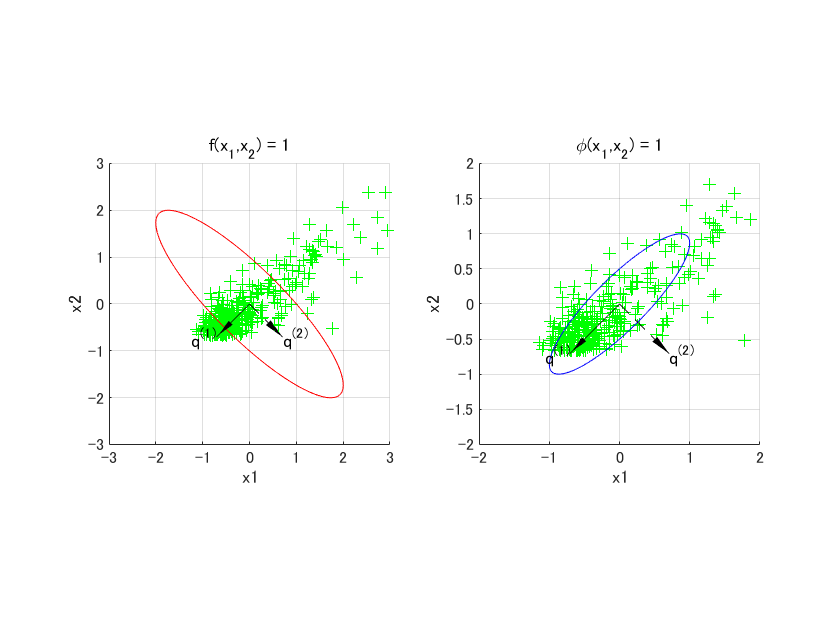

xlabel('x1'); ylabel('x2');
axis([-2 2 -2 2]); axis square;
% add eigen vectors
arrow3([0 0], [Q(1,1) Q(2,1)]); text(Q(1,1),Q(2,1),'q^{(1)}','HorizontalAlignment','right');
arrow3([0 0], [Q(1,2) Q(2,2)],'k--'); text(Q(1,2),Q(2,2),'q^{(2)}');

左図の赤い実線が$f\left(x,\textrm{Vx}\right)=1$で表される楕円で，右側の青い実線が$\phi \left(x,V^{-1} x\right)=1$で表される楕円です．緑色の十字は中心化されたデータの分布です．黒色実線の矢印は分散共分散行列$V$の最大固有値$\lambda_1$に対応する固有ベクトル$q^{\left(1\right)}$を表しています．先程指摘したように，ベクトル$q^{\left(1\right)}$は$V^{-1}$の最小固有値$1/\lambda_1$に対応する固有ベクトルでもあります．また，黒色破線の矢印は分散共分散行列$V$の最小固有値$\lambda_2$に対応する固有ベクトル$q^{\left(2\right)}$を表しています．このベクトル$q^{\left(2\right)}$は$V^{-1}$の最大固有値$1/\lambda_2$に対応する固有ベクトルでもあります．分散共分散行列$V$およびその逆行列$V^{-1}$の固有ベクトルはいずれも同じ向きを表しています．変わるのはそれぞれに対応する固有値であることに注意してください．ベクトル$q^{\left(1\right)}$は分散共分散行列$V$の最大固有値$\lambda_1$に対応する向きを示し，楕円$f\left(x,\textrm{Vx}\right)=1$の短軸方向と一致します（左図）．また，ベクトル$q^{\left(1\right)}$は分散共分散行列$V^{-1}$の最小固有値$1/\lambda_1$に対応する向きも示し，楕円$\phi \left(x,V^{-1} x\right)=1$の長軸方向と一致します（右図）．